# VERSION 1: autocorrelation

% Load the vocal and instrumental waveforms

[vocal, vocal_fs] = audioread('C:\Users\EDCEL\Downloads\Vocali.se_5897\Vocali.se_5897_y2mate.com---Honey-my-Love-So-Sweet-Remastered_vocals.mp3');

[instrumental, instrumental_fs] = audioread('C:\Users\EDCEL\Downloads\Vocali.se_5897\Vocali.se_5897_y2mate.com---Honey-my-Love-So-Sweet-Remastered_music.mp3');

% Ensure both tracks have the same sample rate

if vocal_fs ~= instrumental_fs

    error('Sample rates of the vocal and instrumental tracks must match');

end

% Define parameters

fs = vocal_fs;  % Sampling frequency

frame_size = 0.02;  % 20 ms frame size

frame_length = round(frame_size * fs);  % Frame length in samples

% Plot the waveforms for both the vocal and instrumental tracks

figure;

subplot(2, 1, 1);

time_vocal = (0:length(vocal)-1) / vocal_fs;

plot(time_vocal, vocal);

title('Vocal Track Waveform');

xlabel('Time (seconds)');

ylabel('Amplitude');

grid on;

subplot(2, 1, 2);

time_instrumental = (0:length(instrumental)-1) / instrumental_fs;

plot(time_instrumental, instrumental);

title('Instrumental Track Waveform');

xlabel('Time (seconds)');

ylabel('Amplitude');

grid on;

%% PITCH ANALYSIS

% Use autocorrelation method for pitch detection in the vocal track

pitch_vocal = zeros(floor(length(vocal) / frame_length), 1);

for i = 1:frame_length:length(vocal) - frame_length

    frame = vocal(i:i + frame_length - 1);

    pitch_vocal(ceil(i / frame_length)) = pitch_autocorrelation(frame, fs);

end

% Expected pitch from instrumental (can be melody or reference)

% For simplicity, we'll assume an expected pitch for the demo

expected_pitch = 440; % Hz (A4 note as example)

% Calculate pitch accuracy

tolerance = 50; % Hz tolerance for pitch matching

pitch_errors = abs(pitch_vocal - expected_pitch) > tolerance;

pitch_accuracy = 1 - mean(pitch_errors);  % Ratio of correct pitches

disp(['Pitch Accuracy: ', num2str(pitch_accuracy * 100), '%']);

%% TIMING ANALYSIS

% Detect beats in both the vocal and instrumental tracks

vocal_beats = custom_findpeaks(vocal, fs * 0.5);  % Custom peak detection

instrumental_beats = custom_findpeaks(instrumental, fs * 0.5);  % Custom peak detection

% Calculate timing accuracy by matching closest beats

beat_tolerance = 0.05 * fs;  % Allowable difference of 50 ms

timing_errors = 0;

for i = 1:length(vocal_beats)

    % Find the closest instrumental beat to each vocal beat

    [min_diff, idx] = min(abs(instrumental_beats - vocal_beats(i)));

    % Check if the closest beat is within the tolerance

    if min_diff > beat_tolerance

        timing_errors = timing_errors + 1;  % Count as timing error

    end

end

% Calculate timing accuracy as a ratio of correct timings

timing_accuracy = 1 - (timing_errors / length(vocal_beats));

disp(['Timing Accuracy: ', num2str(timing_accuracy * 100), '%']);

%% FINAL SCORE

% Combine pitch and timing accuracy

final_score = (0.6 * pitch_accuracy) + (0.4 * timing_accuracy);

disp(['Final Karaoke Score: ', num2str(final_score * 100), '/100']);

%% Helper Function: Pitch Detection using Autocorrelation

function pitch = pitch_autocorrelation(frame, fs)

    % Center the frame around 0

    frame = frame - mean(frame);

    % Autocorrelation

    [acf, lags] = xcorr(frame);

    acf = acf(lags >= 0);  % Only keep positive lags

    lags = lags(lags >= 0);

    % Find peaks in the autocorrelation

    locs = custom_findpeaks(acf);  % Custom peak detection

    % Take the first significant peak as the period of the pitch

    if ~isempty(locs)

        period = lags(locs(1));

        pitch = fs / period;

    else

        pitch = NaN;  % No pitch detected

    end

end

%% Helper Function: Custom Peak Detection

function locs = custom_findpeaks(signal, min_distance)

    % Custom peak detection algorithm without the need for Signal Processing Toolbox

    % Arguments:

    % signal: the input waveform (e.g., vocal or instrumental track)

    % min_distance: minimum allowed distance between peaks in samples (optional)

    if nargin < 2

        min_distance = 1;  % Default minimum distance between peaks

    end

    locs = [];  % Initialize an empty list for storing peak indices

    len_signal = length(signal);

    for i = 2:len_signal-1

        % Check if the current sample is greater than the previous and next sample

        if signal(i) > signal(i-1) && signal(i) > signal(i+1)

            % Enforce minimum distance between peaks

            if isempty(locs) || (i - locs(end)) >= min_distance

                locs = [locs, i];  % Add the index of the peak

            end

        end

    end

end

# VERSION 2:YIN

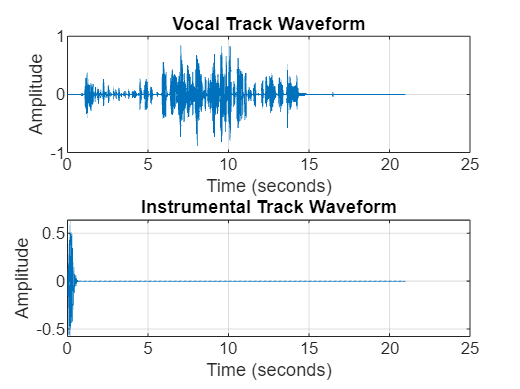

% Load the vocal and instrumental waveforms
A

% Ensure both tracks have the same sample rate
if vocal_fs ~= instrumental_fs
    error('Sample rates of the vocal and instrumental tracks must match');
end

% Define parameters
fs = vocal_fs;  % Sampling frequency
frame_size = 0.02;  % 20 ms frame size
frame_length = round(frame_size * fs);  % Frame length in samples

% Plot the waveforms for both the vocal and instrumental tracks
figure;
subplot(2, 1, 1);
time_vocal = (0:length(vocal)-1) / vocal_fs;
plot(time_vocal, vocal);
title('Vocal Track Waveform');
xlabel('Time (seconds)');
ylabel('Amplitude');
grid on;

subplot(2, 1, 2);
time_instrumental = (0:length(instrumental)-1) / instrumental_fs;
plot(time_instrumental, instrumental);
title('Instrumental Track Waveform');
xlabel('Time (seconds)');
ylabel('Amplitude');
grid on;


%% Melody Extraction for Dynamic Pitch Reference (from the instrumental)
expected_pitch_instrumental = zeros(floor(length(instrumental) / frame_length), 1);
for i = 1:frame_length:length(instrumental) - frame_length
    frame = instrumental(i:i + frame_length - 1);
    expected_pitch_instrumental(ceil(i / frame_length)) = yin_pitch_detection(frame, fs);
end

%% PITCH ANALYSIS (for the vocal track using YIN)
pitch_vocal = zeros(floor(length(vocal) / frame_length), 1);
for i = 1:frame_length:length(vocal) - frame_length
    frame = vocal(i:i + frame_length - 1);
    pitch_vocal(ceil(i / frame_length)) = yin_pitch_detection(frame, fs);
end

% Calculate pitch accuracy by comparing vocal pitch to the dynamic expected pitch
tolerance = 50; % Hz tolerance for pitch matching
pitch_errors = abs(pitch_vocal - expected_pitch_instrumental) > tolerance;
pitch_accuracy = 1 - mean(pitch_errors, 'omitnan');  % Ratio of correct pitches
disp(['Pitch Accuracy: ', num2str(pitch_accuracy * 100), '%']);

Pitch Accuracy: 100%



%% TIMING ANALYSIS (remains the same)
% Detect beats in both the vocal and instrumental tracks
vocal_beats = custom_findpeaks(vocal, fs * 0.5);  % Custom peak detection
instrumental_beats = custom_findpeaks(instrumental, fs * 0.5);  % Custom peak detection

% Calculate timing accuracy by matching closest beats
beat_tolerance = 0.05 * fs;  % Allowable difference of 50 ms
timing_errors = 0;
for i = 1:length(vocal_beats)
    % Find the closest instrumental beat to each vocal beat
    [min_diff, idx] = min(abs(instrumental_beats - vocal_beats(i)));
    
    % Check if the closest beat is within the tolerance
    if min_diff > beat_tolerance
        timing_errors = timing_errors + 1;  % Count as timing error
    end
end

% Calculate timing accuracy as a ratio of correct timings
timing_accuracy = 1 - (timing_errors / length(vocal_beats));
disp(['Timing Accuracy: ', num2str(timing_accuracy * 100), '%']);

Timing Accuracy: 4.7619%



%% FINAL SCORE
% Combine pitch and timing accuracy
final_score = (0.6 * pitch_accuracy) + (0.4 * timing_accuracy);
disp(['Final Karaoke Score: ', num2str(final_score * 100), '/100']);

Final Karaoke Score: 61.9048/100




%% Helper Function: YIN Pitch Detection
function pitch = yin_pitch_detection(frame, fs)
    % Placeholder YIN algorithm for pitch detection
    % You can implement or use an existing YIN function here
    % For now, we return a dummy pitch value (you can replace this with YIN logic)
    
    % Example of simple harmonic mean pitch estimation (replace with real YIN logic)
    [r, lags] = xcorr(frame);  % Autocorrelation as placeholder for YIN
    r = r(lags >= 0);  % Keep positive lags
    lags = lags(lags >= 0);
    [~, idx] = max(r);  % Find maximum peak
    if idx > 1
        period = lags(idx);
        pitch = fs / period;  % Frequency estimate
    else
        pitch = NaN;  % No valid pitch detected
    end
end

%% Helper Function: Custom Peak Detection (same as before)
function locs = custom_findpeaks(signal, min_distance)
    if nargin < 2
        min_distance = 1;  % Default minimum distance between peaks
    end

    locs = [];  % Initialize an empty list for storing peak indices
    len_signal = length(signal);
    
    for i = 2:len_signal-1
        % Check if the current sample is greater than the previous and next sample
        if signal(i) > signal(i-1) && signal(i) > signal(i+1)
            % Enforce minimum distance between peaks
            if isempty(locs) || (i - locs(end)) >= min_distance
                locs = [locs, i];  % Add the index of the peak
            end
        end
    end
end






# VERSION 3: KARAOKE MAKER: FAIL